f = fopen("CAIDA/0000.txt")

f = 6

linedata = fgetl(f);
real_spread_dist = [];
while ~feof(f)
    linedata = fgetl(f);
    if ~isletter(linedata(1))
        numdata = str2num(linedata);
        real_spread_dist = [real_spread_dist,numdata.'];
    else
        break
    end
end

real_HLL_dist = [];
while ~feof(f)
    linedata = fgetl(f);
    if ~isletter(linedata(1))
        numdata = str2num(linedata);
        real_HLL_dist = [real_HLL_dist,numdata.'];
    else
        break
    end
end

real_Bitmap_dist = [];
while ~feof(f)
    linedata = fgetl(f);
    if ~isletter(linedata(1))
        numdata = str2num(linedata);
        real_Bitmap_dist = [real_Bitmap_dist,numdata.'];
    else
        break
    end
end

show_st = 3;
show_end = 50;
hold off
plot(agg_gene_layer1(1,show_st:show_end),agg_gene_layer1(2,show_st:show_end),"LineStyle","--")
hold on;
plot(agg_real_layer1(1,show_st:show_end),agg_real_layer1(2,show_st:show_end),"LineStyle","-.")

show_st = 1;
show_end = 80;
hold off
plot(agg_gene_layer2(1,show_st:show_end),agg_gene_layer2(2,show_st:show_end),"LineStyle","--")
hold on;
plot(agg_real_layer2(1,show_st:show_end),agg_real_layer2(2,show_st:show_end),"LineStyle","-.")

max_spread = real_HLL_dist(1,end) - real_HLL_dist(1,1);
%total_size =  real_spread_dist(1,:) * real_spread_dist(2,:).';
total_flownum = 17743961;
[states,highskew_k,lowskew_k,highskew_rat] = ...
find_opt_k(total_flownum,max_spread,real_Bitmap_dist,real_HLL_dist)

ans = "first stage finished"

states = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.0636    5.9640    3.7149    4.1808    6.0793    5.9785    3.7342    4.4937    4.6550    4.7121
    6.0636    5.9640    3.7149    4.1809    6.0793    5.9785    3.7342    4.4937    4.6550    4.7121
    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0010
    0.0001    0.0002    0.0003    0.0004    0.0001    0.0002    0.0003    0.0004    0.0005    0.0005
    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004


highskew_k = 0.7000

lowskew_k = 0.3000

highskew_rat = 0.4000

highskew_rat = 0.4;
layer1_len = 546133;
layer2_len = 19200;
agg_arr = gene_agg_arr(1.03,400);
highskew_size = floor(total_flownum * highskew_rat);
lowskew_size = total_flownum - highskew_size;
highskew_dist = gen_Zipf(max_spread,highskew_k,highskew_size);
lowskew_dist = gen_Zipf(max_spread * 0.04 , lowskew_k, lowskew_size);
merged_dist = merge_dist(highskew_dist,lowskew_dist);
[bitmap_sketch,hll_sketch] = gene_sketch(layer1_len,layer2_len,merged_dist);
agg_gene_layer1 = sketch2agg_dist(bitmap_sketch,agg_arr);
agg_gene_layer2 = sketch2agg_dist(hll_sketch,agg_arr);
agg_real_layer1 = dist2agg_dist(real_Bitmap_dist,agg_arr);
agg_real_layer2 = dist2agg_dist(real_HLL_dist,agg_arr);

res = sum(merged_dist(2,:))

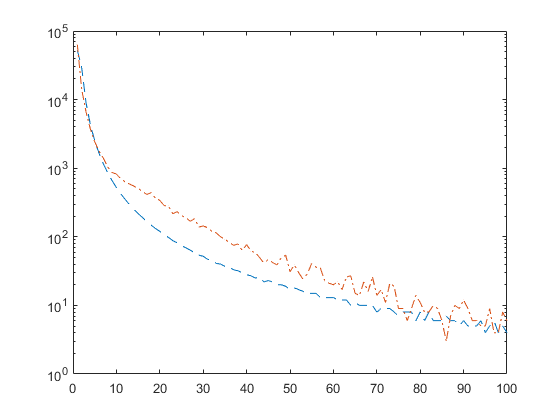

show_st = 1;
show_end = 100;
% hold off
% plot(merged_dist(1,show_st:show_end),merged_dist(2,show_st:show_end))
% hold on
% plot(real_spread_dist(1,show_st:show_end),real_spread_dist(2,show_st:show_end))

hold off

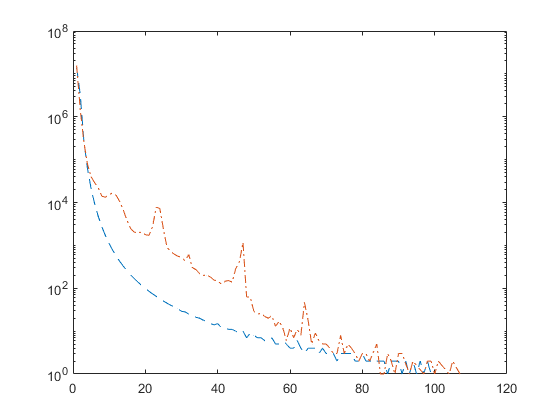

semilogy(merged_dist(1,show_st:show_end),merged_dist(2,show_st:show_end),"LineStyle","--")
hold on
semilogy(real_spread_dist(1,show_st:show_end),real_spread_dist(2,show_st:show_end),"LineStyle","-.")

% show_st = 1;
% show_end = 8;
% hold off;
% plot(agg_gene_layer1(1,show_st:show_end),agg_gene_layer1(2,show_st:show_end),"LineStyle","--")
% hold on;
% plot(agg_real_layer1(1,show_st:show_end),agg_real_layer1(2,show_st:show_end),"LineStyle","-.")

show_st = 1;
show_end = 80;
hold off
plot(agg_gene_layer2(1,show_st:show_end),agg_gene_layer2(2,show_st:show_end),"LineStyle","--")
hold on;
plot(agg_real_layer2(1,show_st:show_end),agg_real_layer2(2,show_st:show_end),"LineStyle","-.")

% t = [-1;2;3;-5];
% t = [-1,2,3,-5];
% res = check_break(t)

for t1 = 1.1:0.1:1.5
    for t2 = 0.3:0.1:0.7
        res = (t1-1.0)/0.1
        round(res)
    end
end

res = 1.0000

ans = 1

res = 1.0000

ans = 1

res = 1.0000

ans = 1

res = 1.0000

ans = 1

res = 1.0000

ans = 1

res = 2.0000

ans = 2

res = 2.0000

ans = 2

res = 2.0000

ans = 2

res = 2.0000

ans = 2

res = 2.0000

ans = 2

res = 3.0000

ans = 3

res = 3.0000

ans = 3

res = 3.0000

ans = 3

res = 3.0000

ans = 3

res = 3.0000

ans = 3

res = 4.0000

ans = 4

res = 4.0000

ans = 4

res = 4.0000

ans = 4

res = 4.0000

ans = 4

res = 4.0000

ans = 4

res = 5

ans = 5

res = 5

ans = 5

res = 5

ans = 5

res = 5

ans = 5

res = 5

ans = 5

function [states,highskew_k,lowskew_k,highskew_rat] = ...
find_opt_k(total_flownum,max_spread,real_Bitmap_dist,real_HLL_dist)
    agg_arr = gene_agg_arr(1.03,400);
    agg_real_layer1 = dist2agg_dist(real_Bitmap_dist,agg_arr);
    agg_real_layer2 = dist2agg_dist(real_HLL_dist,agg_arr);
    layer1_len = 546133;
    layer2_len = 19200;
    layer1_errors = [];
    layer2_errors = [];
    total_errors = [];
    history_error = 1e23;
    for k = 0.3:0.1:2
        zipf_dist = gen_Zipf(max_spread,k,total_flownum);
        [bitmap_sketch,hll_sketch] = gene_sketch(layer1_len,layer2_len,zipf_dist);
        agg_arr = gene_agg_arr(1.03,400);
        agg_gene_layer1 = sketch2agg_dist(bitmap_sketch,agg_arr);
        agg_gene_layer2 = sketch2agg_dist(hll_sketch,agg_arr);
        layer1_error = calc_diff(agg_gene_layer1,agg_real_layer1)/layer1_len;
        layer2_error = calc_diff(agg_gene_layer2,agg_real_layer2)/layer2_len;
        total_error = layer1_error + layer2_error;
        layer1_errors = [layer1_errors,layer1_error];
        layer2_errors = [layer2_errors,layer2_error];
        total_errors = [total_errors,total_error];
        if total_error > history_error
            %break
        end
        history_error = total_error;
    end
    "first stage finished"
    [minval,k] = min(total_errors);
    
    init_k = k*0.1 + 0.3 - 0.1;
    layer1_errors = [];
    layer2_errors = [];
    total_errors = [];
    k_arr = [];
    history_errors = -1 * ones(4,ceil( (init_k-0.1-max(init_k-0.6,0.1))/0.1 ) + 1 );
    for highskew_rat = 0.4:0.1:0.9 
        for k1 = init_k+0.1 : 0.1 : init_k+0.4
            for k2 = max(init_k-0.6,0.1) : 0.1 : init_k-0.1
                k1pos = round( (k1 - init_k) / 0.1 );
                k2pos = round( (k2 + 0.1 - max(init_k-0.6,0.1)) / 0.1 );
                if check_break(history_errors(k1pos,:)) 
                    break;
                end
                if check_break(history_errors(:,k2pos))
                    continue;
                end
                highskew_size = floor(total_flownum * highskew_rat);
                lowskew_size = total_flownum - highskew_size;
                highskew_dist = gen_Zipf(max_spread,k1,highskew_size);
                lowskew_dist = gen_Zipf(max_spread * 0.04 , k2 , lowskew_size);
                merged_dist = merge_dist(highskew_dist,lowskew_dist);
                [bitmap_sketch,hll_sketch] = gene_sketch(layer1_len,layer2_len,merged_dist);
                agg_gene_layer1 = sketch2agg_dist(bitmap_sketch,agg_arr);
                agg_gene_layer2 = sketch2agg_dist(hll_sketch,agg_arr);
                
                layer1_error = calc_diff(agg_gene_layer1,agg_real_layer1)/layer1_len;
                layer2_error = calc_diff(agg_gene_layer2,agg_real_layer2)/layer2_len;
                total_error = layer1_error + layer2_error;
                layer1_errors = [layer1_errors,layer1_error];
                layer2_errors = [layer2_errors,layer2_error];
                total_errors = [total_errors,total_error];
                k_arr = [k_arr,[k1;k2;highskew_rat]];
                
                history_errors(k1pos,k2pos) = total_error;
            end
        end
    end
%     [l1sorted,l1_initpos] = sort(layer1_errors(1,:));
%     [l2sorted,l2_initpos] = sort(layer2_errors(1,:));
%     orders_len = size(l1_initpos,2);
%     layer1_orders = zeros(1,orders_len);
%     layer2_orders = zeros(1,orders_len);
%     
%     for i = 1:1:orders_len
%         layer1_orders(1,l1_initpos(1,i)) = i;
%         layer2_orders(1,l2_initpos(1,i)) = i;
%     end
%     total_orders = layer1_orders + layer2_orders;
    [minval,idx] = min(total_errors);
    highskew_k = k_arr(1,idx);
    lowskew_k = k_arr(2,idx);
    highskew_rat = k_arr(3,idx);
    states = [layer1_errors;layer2_errors;total_errors;k_arr];
end  

function res = check_break(vec)
    if size(vec,1) ~= 1
        vec = vec.';
    end
    vec = vec(vec>0);
    if size(vec,2) == 0
        res = false;
        return
    end
    [minval,minidx] = min(vec);
    if minidx ~= size(vec,2)
        res = true;
        return
    end
    res = false;
end

function res = merge_dist(dist1,dist2)
    dist_merge = [];
    len1 = size(dist1,2);
    len2 = size(dist2,2);
    idx1 = 1;
    idx2 = 1;
    while idx1 <= len1 || idx2 <= len2
        if idx2 > len2 || idx1 > len1
            if idx1 <= len1
                dist_merge = [dist_merge,dist1(:,idx1)];
                idx1 = idx1 + 1;
            else
                dist_merge = [dist_merge,dist2(:,idx2)];
                idx2 = idx2 + 1;
            end
            continue;
        end
        if dist1(1,idx1) < dist2(1,idx2)
            dist_merge = [dist_merge,dist1(:,idx1)];
            idx1 = idx1 + 1;
        elseif dist1(1,idx1) > dist2(1,idx2)
            dist_merge = [dist_merge,dist2(:,idx2)];
            idx2 = idx2 + 1;
        else
            dist_merge = [dist_merge,dist1(:,idx1)];
            dist_merge(2,end) = dist_merge(2,end) + dist2(2,idx2);
            idx1 = idx1 + 1;
            idx2 = idx2 + 1;
        end
    end
    res = dist_merge;
    %dist_merge
end

function [bitmap_sketch,hll_sketch] = gene_sketch(layer1_len,layer2_len,data_dist)
    dist_len = size(data_dist,2);
    bitmap_sketch = zeros(1,layer1_len);
    hll_sketch = zeros(1,layer2_len);
    for i = 1:1:dist_len
        cur_spread = floor(data_dist(1,i));
        cur_num = data_dist(2,i);
        layer1_poses = ceil(rand(2,cur_num) * layer1_len);
        layer2_poses = ceil(rand(2,cur_num) * layer2_len);
        for j = 1:1:cur_num
            % Layer 1
            pos1_add = sum(randi([0,1],1,cur_spread));
            pos1_add;
            pos2_add = cur_spread - pos1_add;
            pos1_newval = bitmap_sketch(1,layer1_poses(1,j)) + pos1_add;
            pos2_newval = bitmap_sketch(1,layer1_poses(2,j)) + pos2_add;
            layer2_add = 0;
            if size(pos1_newval,1) ~= 1
                size(pos1_newval,1) 
            end
            pos1_exc = (pos1_newval >= 9);
            pos2_exc = (pos2_newval >= 9);
            if pos1_exc && pos2_exc
                layer2_add = pos1_newval - 9 + pos2_newval - 9;
                pos1_newval = 9;
                pos2_newval = 9;
            else
                pos1_newval = min(pos1_newval,9);
                pos2_newval = min(pos2_newval,9);
            end
            bitmap_sketch(1,layer1_poses(1,j)) = pos1_newval;
            bitmap_sketch(1,layer1_poses(2,j)) = pos2_newval;
            % Layer 2
            if layer2_add > 0
                hll_sketch(1,layer2_poses(1,j)) = hll_sketch(1,layer2_poses(1,j)) + layer2_add;
                hll_sketch(1,layer2_poses(2,j)) = hll_sketch(1,layer2_poses(2,j)) + layer2_add;
            end
        end
        
    end
end

% dist1, dist2 in size [2,dist_len]
function res = calc_diff(dist1,dist2)
    dist_len = size(dist1,2);
    err_sum = 0;
    for i = 1:1:dist_len
        diff = dist1(2,i) - dist2(2,i);
        err_sum = err_sum + diff^2;
    end
    res = err_sum;
end
% agg_arr = gene_agg_arr(1.03,300);
% test_sketch = floor(rand(1,2000)*6000);
% dist1 = sketch2agg_dist(test_sketch,agg_arr);
% test_sketch = floor(rand(1,2000)*6000);
% dist2 = sketch2agg_dist(test_sketch,agg_arr);
% diff_12 = calc_diff(dist1,dist2)

function res = gene_agg_arr(exp_val,arr_size)
    agg_arr = [0];
    for i = 2:1:arr_size
        tmp_val = floor(exp_val ^ i) - 1;
        if agg_arr(1,end) ~= tmp_val 
            agg_arr = [agg_arr,tmp_val];
        end
    end
    res = agg_arr;
end

% sketch in size [1,sketch_len]
% agg_arr in size [1,m]
function res = sketch2agg_dist(sketch,agg_arr)
    agg_dist = [agg_arr;zeros(size(agg_arr))];
    sketch_len = size(sketch,2);
    for i = 1:1:sketch_len
        idx = sum(agg_arr<=sketch(1,i));
        agg_dist(2,idx) = agg_dist(2,idx) + 1;
    end
    res = agg_dist;
end

% orig_dist in size [2,dist_len]
% agg_arr in size [1,m]
function res = dist2agg_dist(orig_dist,agg_arr)
    agg_dist = [agg_arr;zeros(size(agg_arr))];
    dist_len = size(orig_dist,2);
    for i = 1:1:dist_len
        idx = sum(agg_arr<=orig_dist(1,i));
        agg_dist(2,idx) = agg_dist(2,idx) + orig_dist(2,i);
    end
    res = agg_dist;
end

% mydist = gen_Zipf(1000,1,100000);
% mydist
% len2show = 20
% plot(mydist(2:len2show,1)',mydist(2:len2show,2)')
function res = gen_Zipf(max_size,k,total_size)
    size_num_arr = [];
    size_num_arr = [size_num_arr;max_size,1];
    flow_num = 1;
    cur_total_size = max_size;
    while true
        if flow_num >= total_size
            break;
        end
        flow_num = flow_num + 1;
        tmp_size = ceil(max_size / (flow_num^k));
        if size_num_arr(end,1) == tmp_size
            size_num_arr(end,2) = size_num_arr(end,2) + 1;
        else
            size_num_arr = [size_num_arr;tmp_size,1];
        end        
        cur_total_size = cur_total_size + tmp_size;
    end
    res = flipud(size_num_arr).';
end